cut_ephys = load_open_ephys_binary('/lampllab/Data/ION_control/Cut_2021-05-10_18-28-52_BC1137/Record Node 102/experiment1/recording1/structure.oebin','continuous',1,'mmap');

Error using fileread
Could not open file /lampllab/Data/ION_control/Cut_2021-05-10_18-28-52_BC1137/Record Node 102/experiment1/recording1/structure.oebin. No such file or directory.

Error in load_open_ephys_binary (line 55)
json=jsondecode(fileread(jsonFile));

Intact_full =load_open_ephys_binary('/lampllab/Data/ION_control/Intact_2021-05-10_16-41-45_BC/Record Node 102/experiment1/recording1/structure.oebin','continuous',1,'mmap');

Error using fileread
Could not open file /lampllab/Data/ION_control/Intact_2021-05-10_16-41-45_BC/Record Node 102/experiment1/recording1/structure.oebin. No such file or directory.

Error in load_open_ephys_binary (line 55)
json=jsondecode(fileread(jsonFile));

Galvo_cut = cut_ephys.Data.Data.mapped(34,:);

Unable to resolve the name 'cut_ephys.Data.Data.mapped'.

Galvo_cut = Galvo_cut - mean(Galvo_cut)
plot(Galvo_cut)
Galvo_cut = double(Galvo_cut);

Galvo_intact = Intact_full.Data.Data.mapped(34,:);

Unable to resolve the name 'Intact_full.Data.Data.mapped'.

Galvo_intact = Galvo_intact - mean(Galvo_intact)
plot(Galvo_intact)
Galvo_intact = double(Galvo_intact);

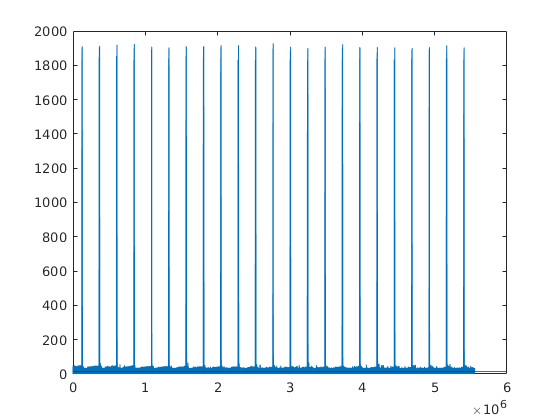

cut_times = event_detection(Galvo_cut,1)

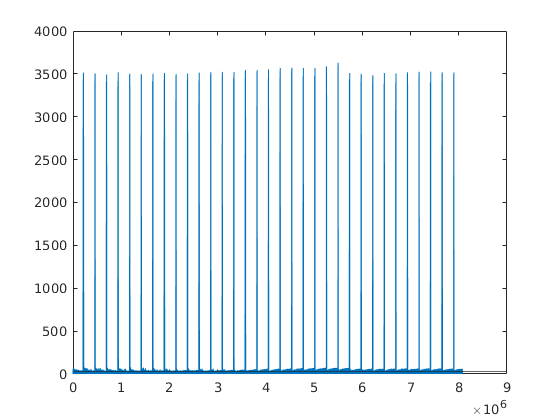


thr =

     []



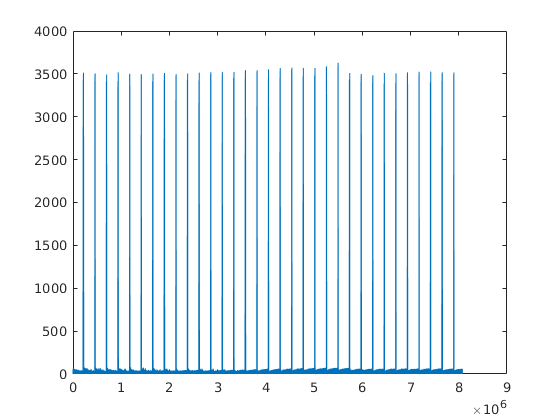

Error using yline (line 29)
Value must be nonempty.

Error in event_detection (line 17)
yline(thr);

times = event_detection(Galvo_intact,1)

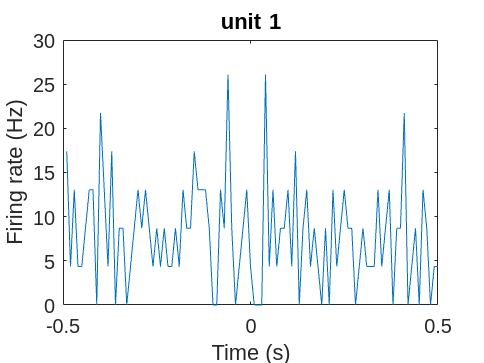

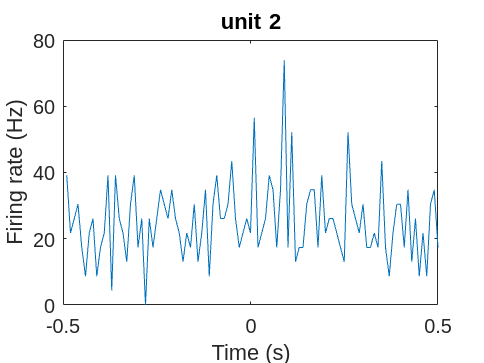

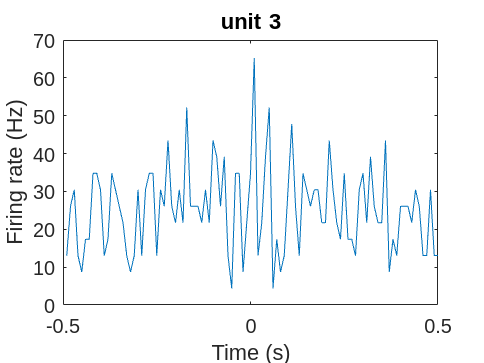

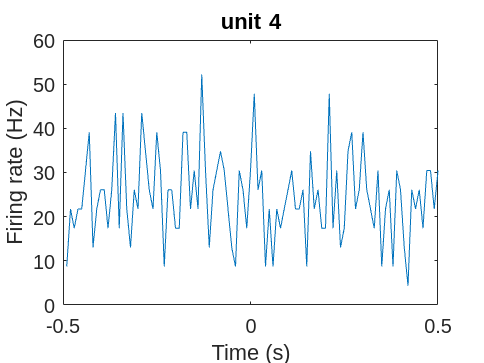

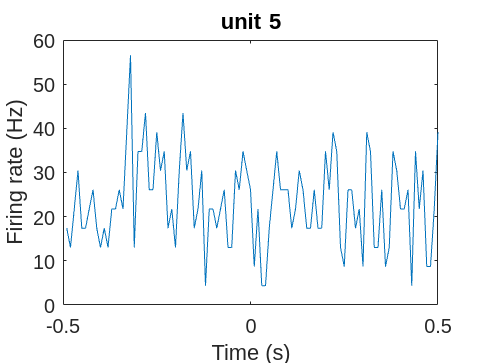

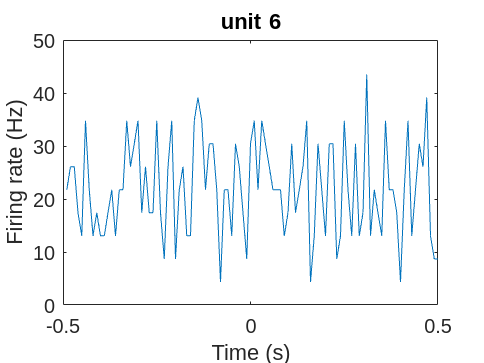

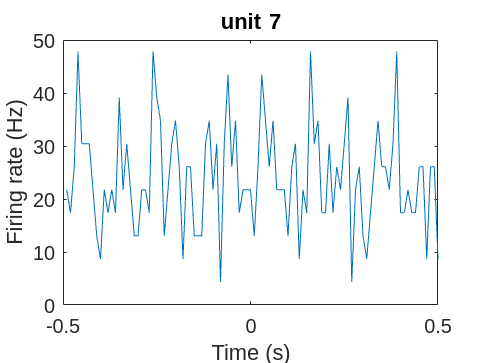

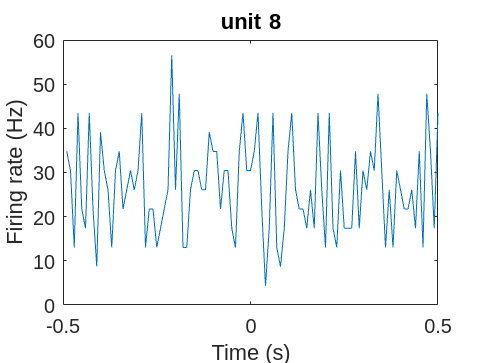

PSTH_Cut = struct with fields:
           good: [17.3913 4.3478 13.0435 4.3478 4.3478 8.6957 13.0435 13.0435 0 21.7391 13.0435 4.3478 17.3913 0 8.6957 8.6957 0 4.3478 8.6957 13.0435 8.6957 13.0435 8.6957 4.3478 8.6957 4.3478 8.6957 4.3478 4.3478 8.6957 4.3478 13.0435 8.6957 8.6957 … ]
            mua: [28×100 double]
          stats: [29×2 double]
    time_vector: [-0.4900 -0.4800 -0.4700 -0.4600 -0.4500 -0.4400 -0.4300 -0.4200 -0.4100 -0.4000 -0.3900 -0.3800 -0.3700 -0.3600 -0.3500 -0.3400 -0.3300 -0.3200 -0.3100 -0.3000 -0.2900 -0.2800 -0.2700 -0.2600 -0.2500 -0.2400 -0.2300 -0.2200 -0.2100 … ]
         United: [29×100 double]


PSTH_Cut = mean_psth(galvoStartsC,cut,1,10)

STD_Cut = std(PSTH_CUT_all)/sqrt(29)

STD_Cut =     0.0202    0.0198    0.0189    0.0217    0.0201    0.0214    0.0184    0.0219    0.0228    0.0173    0.0191    0.0186    0.0152    0.0193    0.0153    0.0133    0.0214    0.0193    0.0211    0.0236    0.0222    0.0215    0.0162    0.0233    0.0183    0.0137    0.0243    0.0194    0.0234    0.0203    0.0155    0.0197    0.0238    0.0201    0.0165    0.0236    0.0229    0.0175    0.0221    0.0220    0.0238    0.0187    0.0183    0.0224    0.0163    0.0221    0.0197    0.0205    0.0177    0.0306


STD_Intact = std(PSTH_Intact_all)/sqrt(29)

STD_Intact =     0.0248    0.0211    0.0182    0.0196    0.0221    0.0175    0.0226    0.0189    0.0189    0.0233    0.0178    0.0180    0.0215    0.0210    0.0212    0.0214    0.0177    0.0195    0.0186    0.0169    0.0199    0.0212    0.0209    0.0184    0.0208    0.0206    0.0206    0.0157    0.0220    0.0220    0.0200    0.0215    0.0208    0.0256    0.0183    0.0203    0.0210    0.0248    0.0183    0.0178    0.0181    0.0171    0.0183    0.0231    0.0224    0.0230    0.0202    0.0189    0.0152    0.0168



CUT_1 = mean(PSTH_CUT_all) + STD_Cut;
CUT_2 = mean(PSTH_CUT_all) - STD_Cut;

Intact_1 = mean(PSTH_Intact_all) + STD_Intact;
Intact_2 = mean(PSTH_Intact_all) - STD_Intact;


figure;
hold on
time2 = [time_vector,fliplr(time_vector)]

time2 =    -0.4900   -0.4800   -0.4700   -0.4600   -0.4500   -0.4400   -0.4300   -0.4200   -0.4100   -0.4000   -0.3900   -0.3800   -0.3700   -0.3600   -0.3500   -0.3400   -0.3300   -0.3200   -0.3100   -0.3000   -0.2900   -0.2800   -0.2700   -0.2600   -0.2500   -0.2400   -0.2300   -0.2200   -0.2100   -0.2000   -0.1900   -0.1800   -0.1700   -0.1600   -0.1500   -0.1400   -0.1300   -0.1200   -0.1100   -0.1000   -0.0900   -0.0800   -0.0700   -0.0600   -0.0500   -0.0400   -0.0300   -0.0200   -0.0100         0


inCut = [CUT_1,fliplr(CUT_2)]

inCut =     0.2451    0.2822    0.2768    0.2705    0.2719    0.2988    0.3182    0.2828    0.2597    0.2527    0.2530    0.2764    0.2536    0.2696    0.2492    0.2442    0.2613    0.2757    0.2505    0.2934    0.2756    0.2584    0.2576    0.2767    0.2822    0.2146    0.2896    0.2833    0.2753    0.2707    0.2613    0.2431    0.2742    0.2644    0.2879    0.2500    0.2643    0.2888    0.2905    0.2633    0.2607    0.2781    0.2642    0.2758    0.2502    0.2785    0.2730    0.2693    0.2561    0.3065


inIntact = [Intact_1,fliplr(Intact_2)]

inIntact =     0.2705    0.2430    0.2359    0.2448    0.2538    0.2395    0.2328    0.2484    0.2344    0.2420    0.2301    0.2217    0.2133    0.2473    0.2367    0.2499    0.2203    0.2188    0.2168    0.2324    0.2419    0.2217    0.2397    0.2372    0.2407    0.2264    0.2221    0.2097    0.2559    0.2386    0.2129    0.2403    0.2417    0.2314    0.2188    0.2315    0.2473    0.2565    0.2435    0.2624    0.2455    0.2359    0.2392    0.2343    0.2616    0.2493    0.2239    0.2420    0.2113    0.2162


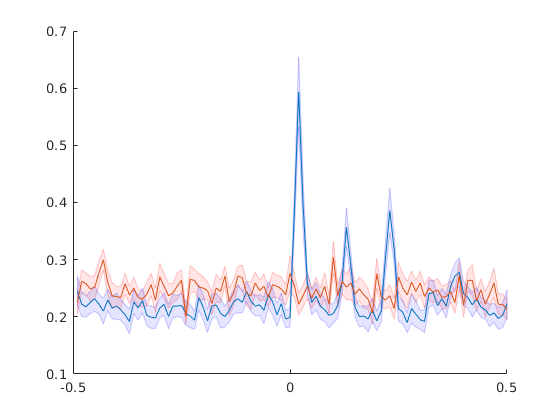

hold on
fill(time2,inCut,'r','FaceAlpha',0.1,'EdgeColor','r','EdgeAlpha',0.2)
fill(time2,inIntact,'b','FaceAlpha',0.1,'EdgeColor','b','EdgeAlpha',0.2)

hold on
plot(time_vector,mean(PSTH_Intact_all))
plot(time_vector,mean(PSTH_CUT_all))

LFP_Int_wind = ones(length(times),30000)

LFP_Int_wind =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1    

Open_time_vec = -14999:15000;

LFP_Int_wind = LFP_Int_wind .*Open_time_vec

LFP_Int_wind =       -14999      -14998      -14997      -14996      -14995      -14994      -14993      -14992      -14991      -14990      -14989      -14988      -14987      -14986      -14985      -14984      -14983      -14982      -14981      -14980      -14979      -14978      -14977      -14976      -14975      -14974      -14973      -14972      -14971      -14970      -14969      -14968      -14967      -14966      -14965      -14964      -14963      -14962      -14961      -14960      -14959      -14958      -14957      -14956      -14955      -14954      -14953      -14952      -14951      -14950
      -14999      -14998      -14997      -14996      -14995      -14994      -14993      -14992      -14991      -14990      -14989      -14988      -14987      -14986      -14985      -14984      -14983      -14982      -14981      -14980      -14979      -14978      -14977      -14976      -14975      -14974      -14973      -14972      -14971      -14970      -14969      -14968

LFP_Int_wind = LFP_Int_wind + times;

LFP_Cut_wind = ones(length(cut_times),30000)

LFP_Cut_wind =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1    

LFP_Cut_wind = LFP_Cut_wind .*Open_time_vec

LFP_Cut_wind =       -14999      -14998      -14997      -14996      -14995      -14994      -14993      -14992      -14991      -14990      -14989      -14988      -14987      -14986      -14985      -14984      -14983      -14982      -14981      -14980      -14979      -14978      -14977      -14976      -14975      -14974      -14973      -14972      -14971      -14970      -14969      -14968      -14967      -14966      -14965      -14964      -14963      -14962      -14961      -14960      -14959      -14958      -14957      -14956      -14955      -14954      -14953      -14952      -14951      -14950
      -14999      -14998      -14997      -14996      -14995      -14994      -14993      -14992      -14991      -14990      -14989      -14988      -14987      -14986      -14985      -14984      -14983      -14982      -14981      -14980      -14979      -14978      -14977      -14976      -14975      -14974      -14973      -14972      -14971      -14970      -14969      -14968

LFP_Cut_wind = LFP_Cut_wind + cut_times

LFP_Cut_wind =       106842      106843      106844      106845      106846      106847      106848      106849      106850      106851      106852      106853      106854      106855      106856      106857      106858      106859      106860      106861      106862      106863      106864      106865      106866      106867      106868      106869      106870      106871      106872      106873      106874      106875      106876      106877      106878      106879      106880      106881      106882      106883      106884      106885      106886      106887      106888      106889      106890      106891
      346849      346850      346851      346852      346853      346854      346855      346856      346857      346858      346859      346860      346861      346862      346863      346864      346865      346866      346867      346868      346869      346870      346871      346872      346873      346874      346875      346876      346877      346878      346879      346880

[b,a] = butter(3,[5,100]/15000,'bandpass')

b = 	1.0e+-5 *

    0.0965         0   -0.2896         0    0.2896         0   -0.0965


a =     1.0000   -5.9601   14.8016  -19.6048   14.6065   -5.8041    0.9610


Cut_LFP = filtfilt(b,a,double(cut_ephys.Data.Data.mapped(30,:)))

Cut_LFP =     9.4827    8.9896    8.5037    8.0251    7.5541    7.0907    6.6351    6.1875    5.7480    5.3167    4.8939    4.4796    4.0740    3.6772    3.2893    2.9105    2.5409    2.1806    1.8297    1.4883    1.1565    0.8344    0.5222    0.2198   -0.0726   -0.3549   -0.6272   -0.8891   -1.1409   -1.3823   -1.6133   -1.8339   -2.0440   -2.2435   -2.4325   -2.6110   -2.7787   -2.9359   -3.0824   -3.2182   -3.3434   -3.4578   -3.5616   -3.6547   -3.7372   -3.8090   -3.8703   -3.9209   -3.9610   -3.9905


Cut_LFP_Event = Cut_LFP(LFP_Cut_wind)

Cut_LFP_Event =   -52.1917  -51.7820  -51.3724  -50.9626  -50.5528  -50.1429  -49.7328  -49.3225  -48.9120  -48.5011  -48.0899  -47.6783  -47.2663  -46.8537  -46.4406  -46.0269  -45.6126  -45.1975  -44.7817  -44.3650  -43.9475  -43.5290  -43.1096  -42.6892  -42.2676  -41.8449  -41.4210  -40.9958  -40.5693  -40.1415  -39.7122  -39.2814  -38.8491  -38.4152  -37.9797  -37.5425  -37.1036  -36.6628  -36.2202  -35.7758  -35.3293  -34.8809  -34.4305  -33.9780  -33.5234  -33.0666  -32.6076  -32.1463  -31.6828  -31.2170
   97.6440   98.6294   99.6239  100.6273  101.6396  102.6605  103.6900  104.7278  105.7739  106.8281  107.8902  108.9601  110.0376  111.1226  112.2149  113.3144  114.4209  115.5342  116.6543  117.7808  118.9138  120.0529  121.1981  122.3493  123.5061  124.6686  125.8365  127.0097  128.1880  129.3712  130.5593  131.7521  132.9493  134.1510  135.3568  136.5667  137.7805  138.9981  140.2194  141.4441  142.6721  143.9034  145.1377  146.3749  147.6149  148.8576  150.1027  151.3503  1

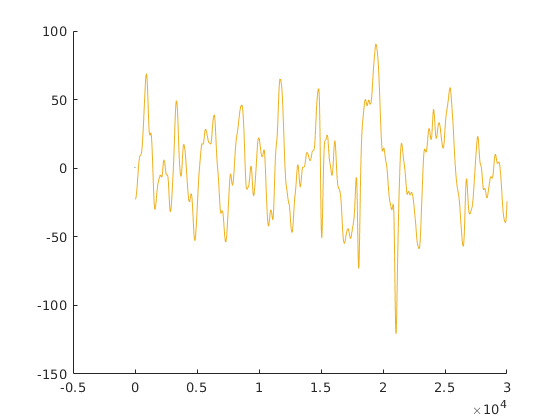

plot(mean(Cut_LFP_Event))

int_LFP = filtfilt(b,a,double(Intact_full.Data.Data.mapped(30,:)))

int_LFP = 	1.0e+03 *

    0.0143    0.0137    0.0130    0.0124    0.0117    0.0111    0.0104    0.0098    0.0091    0.0085    0.0078    0.0072    0.0065    0.0058    0.0052    0.0045    0.0038    0.0032    0.0025    0.0018    0.0012    0.0005   -0.0001   -0.0008   -0.0015   -0.0021   -0.0028   -0.0035   -0.0041   -0.0048   -0.0054   -0.0061   -0.0067   -0.0074   -0.0080   -0.0087   -0.0093   -0.0099   -0.0106   -0.0112   -0.0118   -0.0125   -0.0131   -0.0137   -0.0143   -0.0149   -0.0155   -0.0161   -0.0167   -0.0173


Int_LFP_Ev = int_LFP(LFP_Int_wind)

Int_LFP_Ev = 	1.0e+03 *

   -0.0101   -0.0106   -0.0111   -0.0115   -0.0120   -0.0124   -0.0129   -0.0133   -0.0137   -0.0142   -0.0146   -0.0150   -0.0154   -0.0158   -0.0162   -0.0166   -0.0170   -0.0174   -0.0177   -0.0181   -0.0185   -0.0188   -0.0192   -0.0195   -0.0198   -0.0202   -0.0205   -0.0208   -0.0211   -0.0214   -0.0217   -0.0220   -0.0223   -0.0226   -0.0228   -0.0231   -0.0233   -0.0236   -0.0238   -0.0241   -0.0243   -0.0245   -0.0247   -0.0249   -0.0251   -0.0253   -0.0254   -0.0256   -0.0258   -0.0259
    0.0707    0.0708    0.0709    0.0710    0.0711    0.0712    0.0713    0.0714    0.0714    0.0715    0.0716    0.0716    0.0717    0.0717    0.0717    0.0718    0.0718    0.0718    0.0718    0.0718    0.0718    0.0718    0.0718    0.0718    0.0717    0.0717    0.0717    0.0716    0.0716    0.0715    0.0714    0.0714    0.0713    0.0712    0.0711    0.0710    0.0709    0.0708    0.0707    0.0706    0.0705    0.0704    0.0702    0.0701    0.0699    0.0698    0.0696    

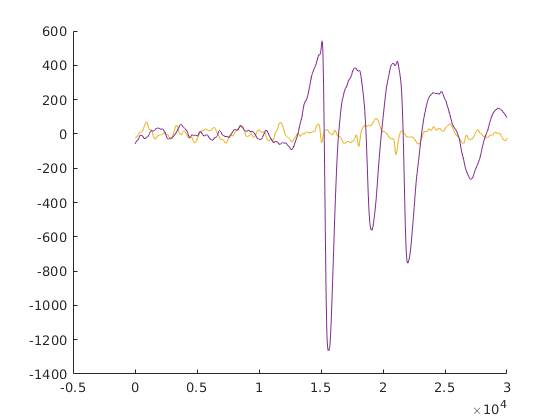

plot(mean(Int_LFP_Ev))

Open_time = Open_time_vec/30000;

STD_Cut_LFP = std(Cut_LFP_Event)/sqrt(23)

STD_Cut_LFP =    35.5482   35.5975   35.6463   35.6946   35.7423   35.7895   35.8361   35.8822   35.9277   35.9726   36.0169   36.0606   36.1036   36.1461   36.1879   36.2290   36.2695   36.3093   36.3485   36.3869   36.4247   36.4618   36.4981   36.5338   36.5687   36.6029   36.6364   36.6691   36.7010   36.7323   36.7627   36.7924   36.8214   36.8496   36.8770   36.9036   36.9294   36.9545   36.9788   37.0022   37.0249   37.0469   37.0680   37.0883   37.1078   37.1265   37.1445   37.1616   37.1780   37.1935


STD_Intact_LFP = std(Int_LFP_Ev)/sqrt(32)

STD_Intact_LFP =    30.8037   30.7711   30.7384   30.7055   30.6723   30.6391   30.6056   30.5720   30.5382   30.5043   30.4703   30.4362   30.4019   30.3675   30.3331   30.2986   30.2640   30.2293   30.1946   30.1599   30.1252   30.0905   30.0558   30.0211   29.9864   29.9518   29.9173   29.8829   29.8485   29.8143   29.7802   29.7462   29.7124   29.6788   29.6454   29.6122   29.5792   29.5465   29.5140   29.4818   29.4499   29.4183   29.3870   29.3561   29.3255   29.2953   29.2655   29.2361   29.2071   29.1785



CUT_1_LFP = mean(Cut_LFP_Event) + STD_Cut_LFP;
CUT_2_LFP = mean(Cut_LFP_Event) - STD_Cut_LFP;

Intact_1_LFP = mean(Int_LFP_Ev) + STD_Intact_LFP;
Intact_2_LFP = mean(Int_LFP_Ev) - STD_Intact_LFP;

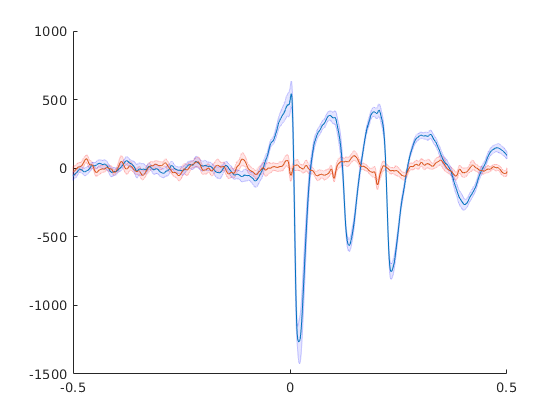

figure;
time2LFP = [Open_time,fliplr(Open_time)];
inCutLFP = [CUT_1_LFP,fliplr(CUT_2_LFP)];
inIntactLFP = [Intact_1_LFP,fliplr(Intact_2_LFP)];
hold on
fill(time2LFP,inCutLFP,'r','FaceAlpha',0.1,'EdgeColor','r','EdgeAlpha',0.2)
fill(time2LFP,inIntactLFP,'b','FaceAlpha',0.1,'EdgeColor','b','EdgeAlpha',0.2)


plot(Open_time,mean(Int_LFP_Ev))
plot(Open_time,mean(Cut_LFP_Event))

LFP_in = sum(Int_LFP_Ev(:, ...
    15000:end),2) - sum(Int_LFP_Ev(:, ...
    1:14999),2)

LFP_in = 	1.0e+06 *

   -1.2915
   -0.3552
   -1.2406
   -1.0895
   -0.0816
    0.5105
   -1.1557
   -0.4726
   -1.3968
   -0.9734


LFP_Cut = sum(Cut_LFP_Event(:, ...
    15000:end),2) - sum(Cut_LFP_Event(:, ...
    1:14999),2)

LFP_Cut = 	1.0e+05 *

   -0.3887
   -0.3223
    1.3669
    0.1539
    1.4807
   -0.4442
   -4.9938
    0.5864
   -4.0372
   -1.2376


ranksum(LFP_in,LFP_Cut)

ans = 7.8217e-07

sum(LFP_Int_wind(:, ...
    15000:end),2)

ans = 	1.0e+11 *

    0.0329
    0.0689
    0.1049
    0.1409
    0.1769
    0.2129
    0.2489
    0.2849
    0.3209
    0.3569


sum(LFP_Int_wind(:, ...
    1:14999),2)

ans = 	1.0e+11 *

    0.0307
    0.0667
    0.1027
    0.1386
    0.1746
    0.2106
    0.2466
    0.2826
    0.3186
    0.3546
